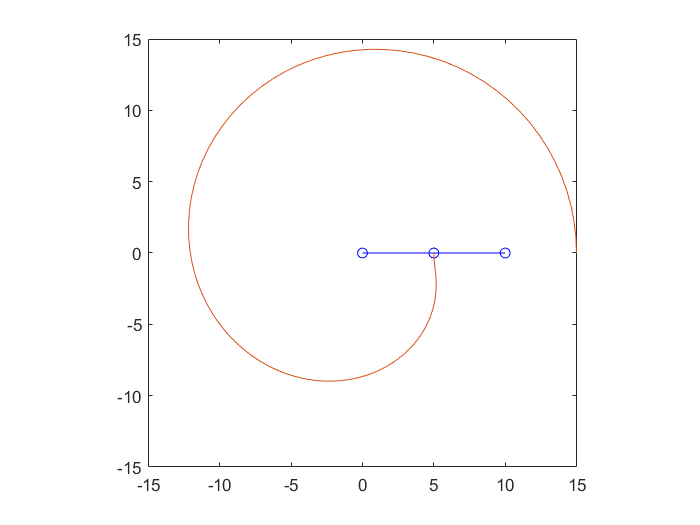

%tracking a point

t=0:0.1:10;
l1=10;
l2=5;

th1=linspace(0,2*pi,length(t));
th2=linspace(0,2*pi,length(t));
y3 = l1*sin(th1)+l2*sin(th1+th2);
x3= l1*cos(th1)+l2*cos(th1+th2);
for i=1:length(t)
    x=[0 l1*cos(th1(i)) l1*cos(th1(i))+l2*cos(th1(i)+th2(i))];
    y=[0 l1*sin(th1(i)) l1*sin(th1(i))+l2*sin(th1(i)+th2(i))];
    
    plot(x,y,'b-o');
     axis([-15 15 -15 15]);
    axis square;
    hold on;
    plot(x3(1:i),y3(1:i));
    axis square;
    hold off;
    pause(0.01);
end